## **Read , plot and set tdms metaproperties**

tdmsFileName="20241105-133105 FD Curve 10.tdms";% Input the filename for reading and plotting.

tdms_time = tdmsread( tdmsFileName,ChannelGroupName="ChannelGroup1",ChannelName="timestamp");
tdms_force=tdmsread( tdmsFileName,ChannelGroupName="ChannelGroup1",ChannelName="force2x");
tdms_distance=tdmsread( tdmsFileName,ChannelGroupName="ChannelGroup1",ChannelName="distance");

T=tdms_time{1}{:,"timestamp"}

T =          0
    0.1191
    0.2382
    0.3572
    0.4763
    0.5954
    0.7145
    0.8335
    0.9526
    1.0717


F=tdms_force{1}{:,"force2x"}

F =     0.1696
    0.1833
   -0.0430
   -0.5382
   -1.0677
   -1.6106
   -2.1550
   -2.8435
   -3.4857
   -4.4602


D=tdms_distance{1}{:,"distance"}

D =    12.4530
   12.4956
   12.6049
   12.7195
   12.8309
   12.9404
   13.0496
   13.1591
   13.2720
   13.3727


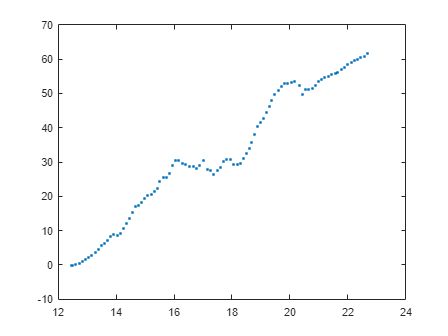

plot(D,-F,'MarkerFaceColor',[0 0.447058823529412 0.741176470588235],...
    'MarkerSize',2,...
    'Marker','o',...
    'LineStyle','none');


% Set Metaproperties

%% Specify the folder containing your .tdms files

folder = "I:\optical tweezer\dna pulling\new project\raw_lambda_before_jump\set4"; % Replace with your actual folder path


% Find all .tdms files in the folder
fileInfo = dir(fullfile(folder, '*.tdms'));
% Loop through each .TDMS file
for n = 1:length(fileInfo)
    fileName = fileInfo(n).name;
    fullFileName = fullfile(folder, fileName);
        % Write metadata to tdms files --
        tdmswriteprop(fileName,"title"," lambda_dna Data")
        tdmswriteprop(fileName,"description","Set_4",...
        ChannelGroupName="ChannelGroup1")
        tdmswriteprop(fileName,["description", "unit_string"],["time","ns"],ChannelGroupName="ChannelGroup1",ChannelName="timestamp")
        tdmswriteprop(fileName,["description", "unit_string"],["end_to_end_distance","um"],ChannelGroupName="ChannelGroup1",ChannelName="distance")
        tdmswriteprop(fileName,["description", "unit_string"],["force","pN"],ChannelGroupName="ChannelGroup1",ChannelName="force2x")
    
end
info=tdmsinfo("20241105-133004 FD Curve 6.tdms") % Check channel list

info =   TdmsInfo with properties:

           Path: "I:\optical tweezer\dna pulling\new project\raw_lambda_before_jump\set4\20241105-133004 FD Curve 6.tdms"
           Name: "20241105-133004 FD Curve 6.tdms"
    Description: ""
          Title: " lambda_dna Data"
         Author: ""
        Version: "2.0"
    ChannelList: [3×8 table]


info.ChannelList

ans = 3×8 table
    ChannelGroupNumber    ChannelGroupName    ChannelGroupDescription    ChannelName     ChannelDescription      Unit    DataType    NumSamples
    __________________    ________________    _______________________    ___________    _____________________    ____    ________    __________

            1             "ChannelGroup1"             "Set_4"            "timestamp"    "time"                   "ns"    "Double"        94    
            1             "ChannelGroup1"             "Set_4"            "distance"     "end_to_end_distance"    "um"    "Double"        94    
            1             "ChannelGroup1"             "Set_4"            "force2x"      "force"                  "pN"    "Double"      

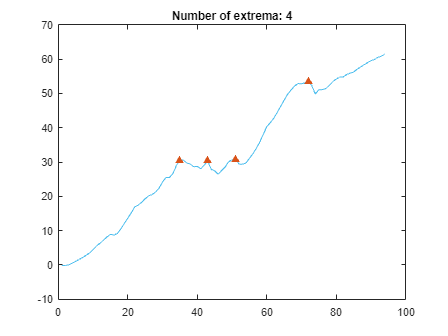




% Analysis fd pattern

% Find local maxima
maxIndices = islocalmax(-F,"MinProminence",0.5,"MaxNumExtrema",10);

% Display results
clf
plot(-F,"Color",[77 190 238]/255)
hold on

% Plot local maxima
plot(find(maxIndices),-F(maxIndices),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255)
title("Number of extrema: " + nnz(maxIndices))
hold off


force1x_max=-F(maxIndices)

force1x_max =    30.5650
   30.3033
   30.8235
   53.3719


index_max=0

index_max = 0

for i=1:length(force1x_max)
    if force1x_max(i)>segmentMean(index+1)
        index_max=index_max+1
    end

end
index_max

index_max = 0

length(force1x_max)-index_max

ans = 4

max(force1x_max(1:end-index_max)) % Maximum_force

ans = 53.3719